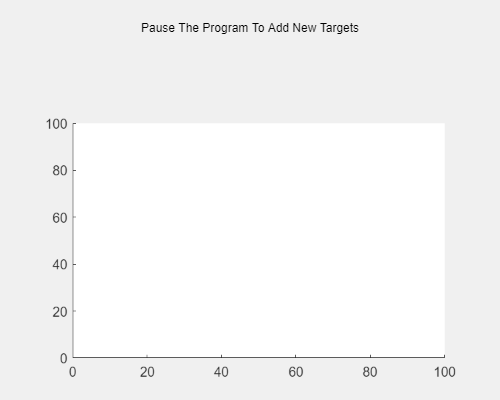

clear
varargout
plotUI = uifigure('Position',[400 100 500 400]);
g1 = uigridlayout(plotUI,[3,2],'RowHeight', {'1x','1x','8x'});   
lbl1 = uilabel(g1,'Text','Pause The Program To Add New Targets');
lbl1.Layout.Column = [1 2];
lbl1.HorizontalAlignment = 'center';
ax1 = axes(g1,'Position',[0.1 0.1 0.7 0.7]);
ax1.Layout.Row = 3;
ax1.Layout.Column = [1 2];
xlim(ax1, [0, 100])
ylim(ax1, [0, 100])

function varargout = untitled(varargin)
    gui_Singleton = 1;
    gui_State = struct('gui_Name',       mfilename, ...
                       'gui_Singleton',  gui_Singleton, ...
                       'gui_OpeningFcn', @untitled_OpeningFcn, ...
                       'gui_OutputFcn',  @untitled_OutputFcn, ...
                       'gui_LayoutFcn',  [] , ...
                       'gui_Callback',   []);
    if nargin && ischar(varargin{1})
        gui_State.gui_Callback = str2func(varargin{1});
    end
    if nargout
        [varargout{1:nargout}] = gui_mainfcn(gui_State, varargin{:});
    else
        gui_mainfcn(gui_State, varargin{:});
    end
end
function untitled_OpeningFcn(hObject, eventdata, handles, varargin)
    h = plot(handles.axes1, rand(10, 1), 'b.-', 'LineWidth', 2, 'MarkerSize', 30);
    grid on;
    xlabel('x');
    ylabel('y');
    set(h,'HitTest','on')
    set(h, 'ButtonDownFcn', @plot_ButtonDownFcn);
    guidata(hObject, handles);
end
function varargout = untitled_OutputFcn(hObject, eventdata, handles) 
    varargout{1} = handles.output;
end
function plot_ButtonDownFcn(hObject, eventdata, handles)
    x = eventdata.IntersectionPoint(1);
    y = eventdata.IntersectionPoint(2);
    line_xs = hObject.XData;
    line_ys = hObject.YData;
    dist2 = (x-line_xs).^2 + (y-line_ys).^2;
    [~,min_idx] = min(dist2);
    closest_x = line_xs(min_idx);
    closest_y = line_ys(min_idx);
    msgbox(sprintf('Clicked on: (%g,%g)\nClosest pt: (%g,%g)',x,y,closest_x,closest_y));
end
